# WATER WAVE

2D Shallow Water Model

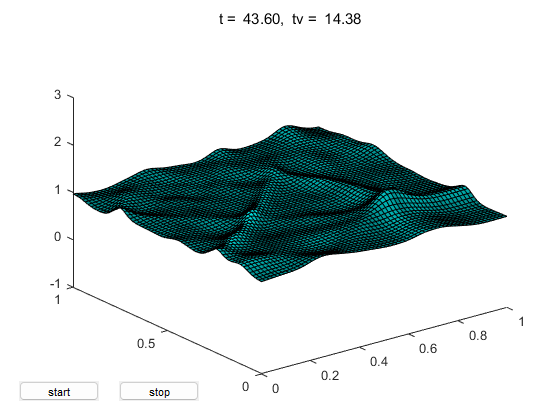

Lax-Wendroff finite difference method. Reflective boundary conditions. Random water drops initiate gravity waves. Surface plot displays height colored by momentum. Plot title shows t = simulated time and tv = a measure of total variation. An exact solution to the conservation law would have constant tv. Lax-Wendroff produces nonphysical oscillations and increasing tv.

Information: Parameters


n = 64;                  % grid size
g = 9.8;                 % gravitational constant
dt = 0.01;               % hardwired timestep
dx = 1.0;
dy = 1.0;
nplotstep = 8;           % plot interval
ndrops = 5;              % maximum number of drops
dropstep = 500;          % drop interval
D = droplet(1.5,21);     % simulate a water drop
 
% Initialize graphics
 
[surfplot,top,start,stop] = initgraphics(n);
 
% Outer loop, restarts.
 
while get(stop,'value') == 0
   set(start,'value',0)
   
   H = ones(n+2,n+2);   U = zeros(n+2,n+2);  V = zeros(n+2,n+2);
   Hx = zeros(n+1,n+1); Ux = zeros(n+1,n+1); Vx = zeros(n+1,n+1);
   Hy = zeros(n+1,n+1); Uy = zeros(n+1,n+1); Vy = zeros(n+1,n+1);
   ndrop = ceil(rand*ndrops);
   nstep = 0;
 
   % Inner loop, time steps.
 
   while get(start,'value')==0 && get(stop,'value')==0
       nstep = nstep + 1;
 
       % Random water drops
       if mod(nstep,dropstep) == 0 && nstep <= ndrop*dropstep
           w = size(D,1);
           i = ceil(rand*(n-w))+(1:w);
           j = ceil(rand*(n-w))+(1:w);
           H(i,j) = H(i,j) + rand*D;
       end
     
       % Reflective boundary conditions
       H(:,1) = H(:,2);      U(:,1) = U(:,2);       V(:,1) = -V(:,2);
       H(:,n+2) = H(:,n+1);  U(:,n+2) = U(:,n+1);   V(:,n+2) = -V(:,n+1);
       H(1,:) = H(2,:);      U(1,:) = -U(2,:);      V(1,:) = V(2,:);
       H(n+2,:) = H(n+1,:);  U(n+2,:) = -U(n+1,:);  V(n+2,:) = V(n+1,:);
 
       % First half step
   
       % x direction
       i = 1:n+1;
       j = 1:n;
   
       % height
       Hx(i,j) = (H(i+1,j+1)+H(i,j+1))/2 - dt/(2*dx)*(U(i+1,j+1)-U(i,j+1));
   
       % x momentum
       Ux(i,j) = (U(i+1,j+1)+U(i,j+1))/2 -  ...
                 dt/(2*dx)*((U(i+1,j+1).^2./H(i+1,j+1) + g/2*H(i+1,j+1).^2) - ...
                            (U(i,j+1).^2./H(i,j+1) + g/2*H(i,j+1).^2));
   
       % y momentum
       Vx(i,j) = (V(i+1,j+1)+V(i,j+1))/2 - ...
                 dt/(2*dx)*((U(i+1,j+1).*V(i+1,j+1)./H(i+1,j+1)) - ...
                            (U(i,j+1).*V(i,j+1)./H(i,j+1)));
       
       % y direction
       i = 1:n;
       j = 1:n+1;
   
       % height
       Hy(i,j) = (H(i+1,j+1)+H(i+1,j))/2 - dt/(2*dy)*(V(i+1,j+1)-V(i+1,j));
   
       % x momentum
       Uy(i,j) = (U(i+1,j+1)+U(i+1,j))/2 - ...
                 dt/(2*dy)*((V(i+1,j+1).*U(i+1,j+1)./H(i+1,j+1)) - ...
                            (V(i+1,j).*U(i+1,j)./H(i+1,j)));
       % y momentum
       Vy(i,j) = (V(i+1,j+1)+V(i+1,j))/2 - ...
                 dt/(2*dy)*((V(i+1,j+1).^2./H(i+1,j+1) + g/2*H(i+1,j+1).^2) - ...
                            (V(i+1,j).^2./H(i+1,j) + g/2*H(i+1,j).^2));
   
       % Second half step
       i = 2:n+1;
       j = 2:n+1;
   
       % height
       H(i,j) = H(i,j) - (dt/dx)*(Ux(i,j-1)-Ux(i-1,j-1)) - ...
                         (dt/dy)*(Vy(i-1,j)-Vy(i-1,j-1));
       % x momentum
       U(i,j) = U(i,j) - (dt/dx)*((Ux(i,j-1).^2./Hx(i,j-1) + g/2*Hx(i,j-1).^2) - ...
                         (Ux(i-1,j-1).^2./Hx(i-1,j-1) + g/2*Hx(i-1,j-1).^2)) ...
                       - (dt/dy)*((Vy(i-1,j).*Uy(i-1,j)./Hy(i-1,j)) - ...
                         (Vy(i-1,j-1).*Uy(i-1,j-1)./Hy(i-1,j-1)));
       % y momentum
       V(i,j) = V(i,j) - (dt/dx)*((Ux(i,j-1).*Vx(i,j-1)./Hx(i,j-1)) - ...
                         (Ux(i-1,j-1).*Vx(i-1,j-1)./Hx(i-1,j-1))) ...
                       - (dt/dy)*((Vy(i-1,j).^2./Hy(i-1,j) + g/2*Hy(i-1,j).^2) - ...
                         (Vy(i-1,j-1).^2./Hy(i-1,j-1) + g/2*Hy(i-1,j-1).^2));
   
       % Update plot
       if mod(nstep,nplotstep) == 0
          C = abs(U(i,j)) + abs(V(i,j));  % Color shows momemtum
          t = nstep*dt;
          tv = norm(C,'fro');
          set(surfplot,'zdata',H(i,j),'cdata',C);
          set(top,'string',sprintf('t = %6.2f,  tv = %6.2f',t,tv))
          drawnow
       end
      
       if all(all(isnan(H))), break, end  % Unstable, restart
   end
end
close(gcf)
 
% ------------------------------------
 

function D = droplet(height,width)
% DROPLET  2D Gaussian
% D = droplet(height,width)
   [x,y] = ndgrid(-1:(2/(width-1)):1);
   D = height*exp(-5*(x.^2+y.^2));
end
% ------------------------------------
 
function [surfplot,top,start,stop] = initgraphics(n)
% INITGRAPHICS  Initialize graphics for waterwave.
% [surfplot,top,start,stop] = initgraphics(n)
% returns handles to a surface plot, its title, and two uicontrol toggles.
 
   clf
   shg
   set(gcf,'numbertitle','off','name','Shallow_water')
   x = (0:n-1)/(n-1);
   surfplot = surf(x,x,ones(n,n),zeros(n,n));
   grid off
   axis([0 1 0 1 -1 3])
   caxis([-1 1])
   shading faceted
   c = (1:64)'/64;
   cyan = [0*c c c];
   colormap(cyan)
   top = title('Click start');
   start = uicontrol('position',[20 20 80 20],'style','toggle','string','start');
   stop = uicontrol('position',[120 20 80 20],'style','toggle','string','stop');
end